# **Aula 01 de CCM 307**

## Boas práticas

clc;                                % limpa a tela
clear all;                          % limpa as variáveis
close all;                          % limpa as figuras

## Lendo um Arquivo WAV e visualizando

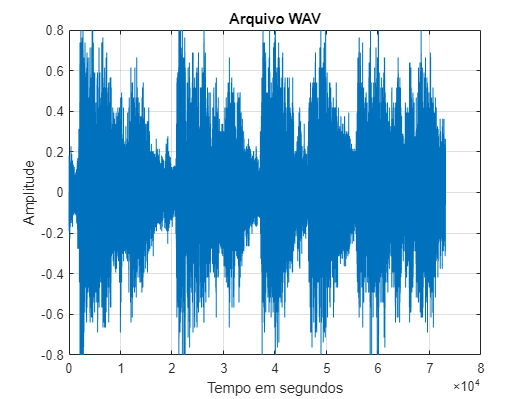

load handel;                        % leitura de um arquivo WAV
sound(2,Fs);                        % ouvindo o arquivo WAV

figure()                            %cria uma figura nova

plot(y)                             % cria o gráfico de amplitude
xlabel('Tempo em segundos')         % nome do eixo x
ylabel('Amplitude')                 % amplitude do sinal
grid                                % cria um reticulado
title('Arquivo WAV')                % nome do gráfico

## Criando uma função handle e visualiazando

f(x,y) = x²+y²

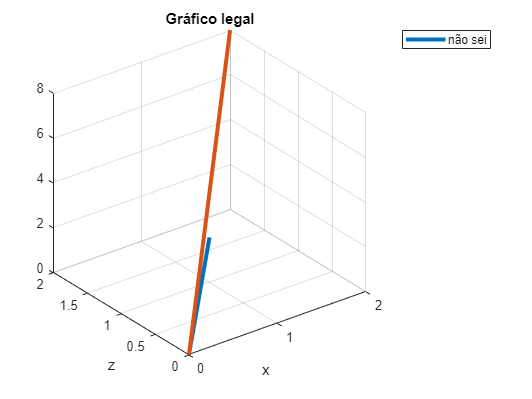

z = @(x,y) x.^2 + y.^2;             % cria uma variável do tipo handle
x = [0,0;1,2];                      % cria valores para x
y = [0,0;1,2];                      % cria valores para y

figure()                            % cria uma figura nova

plot3(x,y,z(x,y),'LineWidth',3)     % cria o gráfico de amplitude
xlabel('x')                         % nome do eixo x
ylabel('y')                         % nome do eixo y
ylabel('z')                         % nome do eixo z
grid                                % cria um reticulado
title('Gráfico legal')              % nome do gráfico
legend('não sei')                   % descrição de variável

## Utilizando variáveis simbólicas

syms x                              % cria uma variável simbólica

resultado = int(x,x,0,1);           % integra x em x de 0 a 1
resultado = eval(resultado)         % transforma em resultado numérico

resultado = 0.5000